PID 제어

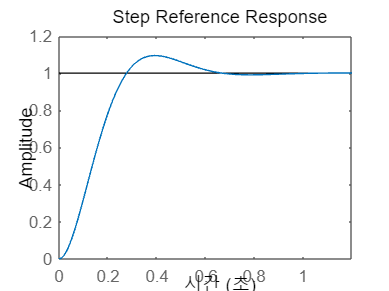

clear
K = 100;
K1 = 12;
s = tf('s');

t_system = 0:0.01:1.2;
r_system = 1;
P_system = 1/(s*(s+K1));

C = K;
sys_cl = feedback(C*P_system,1); %uniti feedback 이니까
figure(1)
step(r_system*sys_cl,t_system);
ylabel('Amplitude');
title('Step Reference Response');

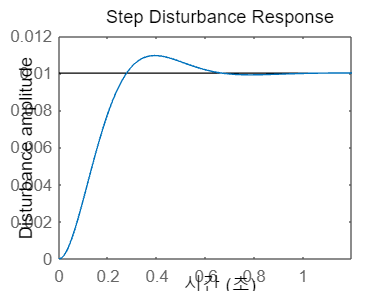

figure(2)
dist_cl = feedback(P_system,C); 
step(dist_cl,t_system)
ylabel('Disturbance amplitude');
title('Step Disturbance Response');

stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.1856
    TransientTime: 0.5943
     SettlingTime: 0.5943
      SettlingMin: 0.9083
      SettlingMax: 1.0948
        Overshoot: 9.4773
       Undershoot: 0
             Peak: 1.0948
         PeakTime: 0.3914


PID Tuner

% pidTuner(P_system, 'pid')